%%% Cargue de segmentación DICOM
%info=dicominfo('/MATLAB Drive/TFM/NCSLC_radiomics/LUNG1-001/09-18-2008-StudyID-NA-69331/3.000000-NA-78236/1-1.dcm')
%info=dicominfo('/MATLAB Drive/TFM/NCSLC_radiomics/LUNG1-003/01-01-2014-StudyID-NA-34270/4.000000-NA-22712/1-1.dcm')
info=dicominfo('/MATLAB Drive/TFM/NSCLC-Radiomics/LUNG1-388/04-17-2010-NA-NA-46237/1.000000-NA-91199/1-1.dcm',UseVRHeuristic=false)

info = struct with fields:
                                   Filename: '/MATLAB Drive/TFM/NSCLC-Radiomics/LUNG1-388/04-17-2010-NA-NA-46237/1.000000-NA-91199/1-1.dcm'
                                FileModDate: '18-Nov-2023 15:20:39'
                                   FileSize: 1821874
                                     Format: 'DICOM'
                              FormatVersion: 3
                                      Width: []
                                     Height: []
                                   BitDepth: []
                                  ColorType: ''
             FileMetaInformationGroupLength: 208
                 FileMetaInformationVersion: [2x1 uint8]
                    MediaStorageSOPClassUID: '1.2.840.10008.5.1.4.1.1.481.3'
                 MediaStorageSOPInstanceUID: '1.3.6.1.4.1.32722.99.99.101660646659787818931106319593884690237'
                          TransferSyntaxUID: '1.2.840.10008.1.2'
                     ImplementationClassUID: '1.3.6.1.4.1.222

%info=dicominfo('/MATLAB Drive/TFM/NSCLC-Radiomics/LUNG1-317/12-03-2008-StudyID-NA-67637/1.000000-NA-84541/1-1.dcm',UseVRHeuristic=false)



rtContours=dicomContours(info);
rtContours.ROIs %Para ver todas las etiquetas/segmentaciones en una tabla y elegir

ans = 6x5 table
    Number         Name          ContourData     GeometricType       Color    
    ______    _______________    ____________    _____________    ____________

      12      {'gtv-2'      }    {  8x1 cell}    {  8x1 cell}     {3x1 double}
      13      {'Lungs-Total'}    {207x1 cell}    {207x1 cell}     {3x1 double}
      14      {'Heart'      }    { 29x1 cell}    { 29x1 cell}     {3x1 double}
      15      {'Esophagus'  }    { 78x1 cell}    { 78x1 cell}     {3x1 double}
      17      {'Spinal-Cord'}    { 93x1 cell}    { 93x1 cell}     {3x1 double}
      24      {'GTV-1'      }    {  9x1 cell}    {  9x1 cell}     {3x1 double}


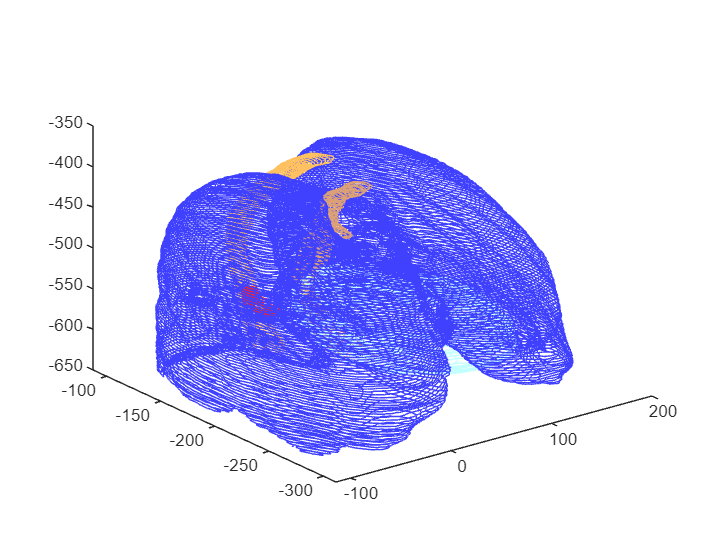

plotContour(rtContours); %Todas las segmentaciones

referenceInfo = imref3d([128 128 50],xlim,ylim,zlim);
% Cree una mascara logica 3D del contorno 19 o 'GTV-1', a partir de rtContours, con referenciacion espacial especificada por el objeto imref3d.
rtMask = createMask(rtContours,'GTV-1',referenceInfo)

rtMask = 128x128x50 logical array
rtMask(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

%Muestra la mascara como una imagen volumetrica.
volshow(rtMask); %se abre en otra ventana con solo el tumor en 3D 

% Intentemos obtener los contornos:
Contour=rtContours.ROIs

Contour = 6x5 table
    Number         Name          ContourData     GeometricType       Color    
    ______    _______________    ____________    _____________    ____________

      12      {'gtv-2'      }    {  8x1 cell}    {  8x1 cell}     {3x1 double}
      13      {'Lungs-Total'}    {207x1 cell}    {207x1 cell}     {3x1 double}
      14      {'Heart'      }    { 29x1 cell}    { 29x1 cell}     {3x1 double}
      15      {'Esophagus'  }    { 78x1 cell}    { 78x1 cell}     {3x1 double}
      17      {'Spinal-Cord'}    { 93x1 cell}    { 93x1 cell}     {3x1 double}
      24      {'GTV-1'      }    {  9x1 cell}    {  9x1 cell}     {3x1 double}


% Encuentra las filas donde el campo 'Name' es 'GTV-1'
indices_GTV1 = strcmp(Contour.Name, 'GTV-1')

indices_GTV1 = 6x1 logical array
   0
   0
   0
   0
   0
   1



% Filtra las filas de la tabla utilizando :
Contour_GTV1 = Contour(indices_GTV1, :);

% Obtiene los datos de la columna 'ContourData' de las filas filtradas
ContourData_GTV1 = Contour_GTV1.ContourData

ContourData_GTV1 = 1x1 cell array
    {9x1 cell}


cellGTV1=ContourData_GTV1{1,1} %accede al contenido de la celda

cellGTV1 = 9x1 cell array
    {32x3 double}
    {38x3 double}
    {62x3 double}
    {76x3 double}
    {70x3 double}
    {72x3 double}
    {54x3 double}
    {54x3 double}
    {44x3 double}


Contorno12=cellGTV1{11} %elige el numero 12, por ejemplo

Index exceeds the number of array elements. Index must not exceed 9.

X12=Contorno12(:,1)
Y12=Contorno12(:,2)
Z12=Contorno12(:,3)
plot3(X12,Y12,Z12)

# box counting fractal dimensions  method

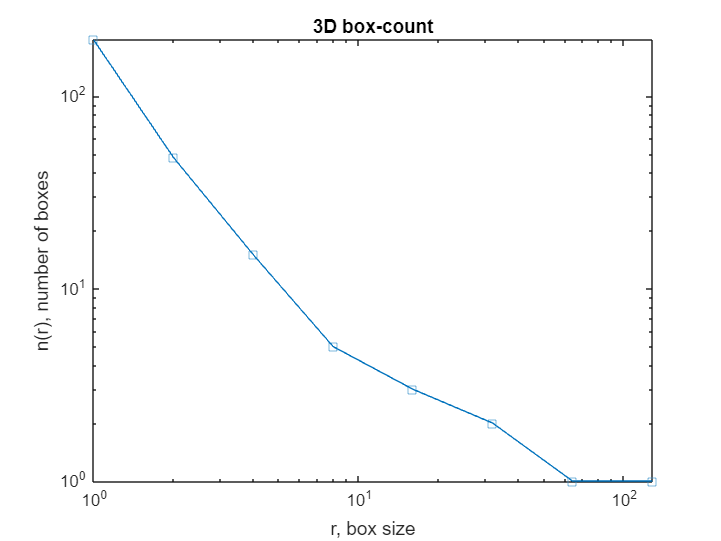

boxcount(rtMask) % crea grafica iterada   de N y epsilon (e) para cobrir ROI del tumor GTV-1

[n, r] = boxcount(rtMask)% extrae el count box(N) y el ratio de epsilon para cubrir la zoan GTV-1

n =    196    48    15     5     3     2     1     1


r =      1     2     4     8    16    32    64   128


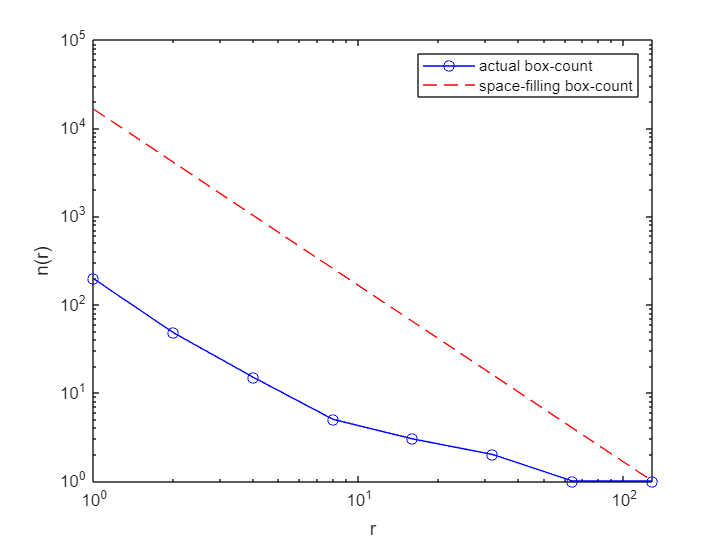

loglog(r, n,'bo-', r, (r/r(end)).^(-2), 'r--')
xlabel('r')
ylabel('n(r)')
legend('actual box-count','space-filling box-count');

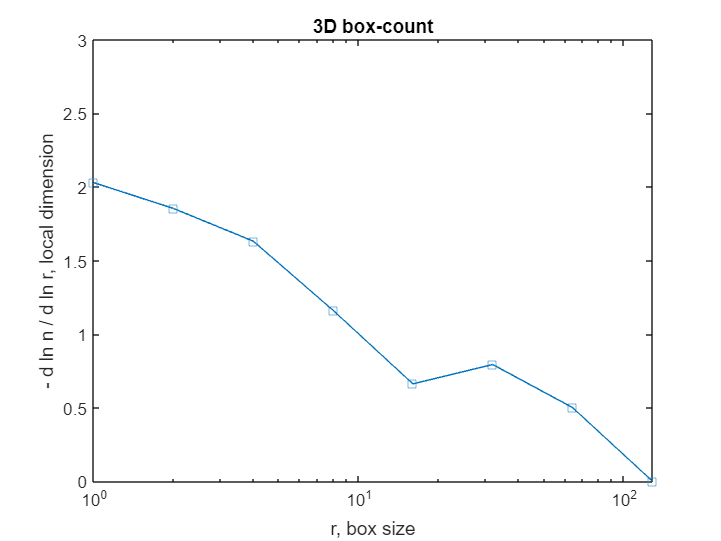

boxcount(rtMask, 'slope')

ec= polyfit(log(r),log(n), 1)

ec =    -1.0796    4.5264


mdl = fitlm(log(r),log(n))

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     4.5264     0.35688     12.683    1.4729e-05
    x1             -1.0796     0.12308    -8.7715    0.00012166


Number of observations: 8, Error degrees of freedom: 6
Root Mean Squared Error: 0.553
R-squared: 0.928,  Adjusted R-Squared: 0.916
F-statistic vs. constant model: 76.9, p-value = 0.000122

plot(mdl)
%hausDim( Contour_GTV1 )


# **Prueba  de  cargue de varias imagenes **

% Especifica la carpeta principal que contiene subcarpetas y archivos DICOM
carpetaPrincipal = '/MATLAB Drive/TFM/NCSLC_radiomics';

% Obtiene la lista de todas las carpetas dentro de la carpeta principal
subCarpetasNivel1 = dir(carpetaPrincipal);
subCarpetasNivel1 = subCarpetasNivel1([subCarpetasNivel1.isdir]); % Filtra solo directorios
subCarpetasNivel1 = subCarpetasNivel1(~ismember({subCarpetasNivel1.name}, {'.', '..'})); % Elimina las carpetas . y ..
% Inicializa una celda para almacenar las imágenes DICOM
imagenesDICOM = cell(0);

% Recorre las subcarpetas del primer nivel
for i = 1:length(subCarpetasNivel1)
    carpetaNivel1 = fullfile(carpetaPrincipal, subCarpetasNivel1(i).name);

    % Obtiene la lista de subcarpetas del segundo nivel
    subCarpetasNivel2 = dir(carpetaNivel1);
    subCarpetasNivel2 = subCarpetasNivel2([subCarpetasNivel2.isdir]); % Filtra solo directorios
    subCarpetasNivel2 = subCarpetasNivel2(~ismember({subCarpetasNivel2.name}, {'.', '..'})); % Elimina las carpetas . y ..
    
    
    % Recorre las subcarpetas del segundo nivel
    for j = 1:length(subCarpetasNivel2)
        carpetaNivel2 = fullfile(carpetaNivel1, subCarpetasNivel2(j).name);

        % Obtiene la lista de subcarpetas del tercer nivel
        subCarpetasNivel3 = dir(carpetaNivel2);
        subCarpetasNivel3 = subCarpetasNivel3([subCarpetasNivel3.isdir]); % Filtra solo directorios
        subCarpetasNivel3 = subCarpetasNivel3(~ismember({subCarpetasNivel3.name}, {'.', '..'})); % Elimina las carpetas . y ..
        % Filtra las subcarpetas del segundo nivel que contienen "Segmentation" en el nombre
        subCarpetasNivel3 = subCarpetasNivel3(~contains({subCarpetasNivel3.name}, 'Segmentation'));
        % Filtra las subcarpetas del segundo nivel que contienen más de un archivo
        subCarpetasNivel3 = subCarpetasNivel3(arrayfun(@(x) numel(dir(fullfile(carpetaNivel2, x.name, '*.dcm')))<2, subCarpetasNivel3));

        

        % Recorre las subcarpetas del tercer nivel
        for k = 1:length(subCarpetasNivel3)
            carpetaNivel3 = fullfile(carpetaNivel2, subCarpetasNivel3(k).name);

            % Obtiene la lista de archivos DICOM en la carpeta actual
            archivosDICOM = dir(fullfile(carpetaNivel3, '*.dcm'));

            % Recorre todos los archivos DICOM en la carpeta actual
            for m = 1:length(archivosDICOM)
                archivoDICOM = fullfile(carpetaNivel3, archivosDICOM(m).name);

                % Lee la imagen DICOM y almacénala en la celda
                imagenDICOM = dicominfo(archivoDICOM);
                imagenesDICOM{end+1} = imagenDICOM;
            end
        end
    end
end


% En este punto, 'imagenesDICOM' contiene todas las imágenes DICOM cargadas desde tres niveles de subcarpetas.
% Puedes acceder a las imágenes individuales utilizando índices en la celda.

% Por ejemplo, para acceder a la primera imagen cargada:
primeraImagen = imagenesDICOM{3};

rtContours=dicomContours(primeraImagen );
rtContours.ROIs

plotContour(rtContours); %Todas las segmentaciones

imagenesDICOM

% Especifica la ruta completa del archivo CSV
rutaCSV = '/MATLAB Drive/NSCLC-Radiomics-Lung1.clinical-version3-Oct-2019.csv';

% Lee el archivo CSV usando readtable
tablaDatos = readtable(rutaCSV);

% Muestra la estructura de la tabla
disp(tablaDatos);
